%%%% ============= Node Wise Similar Load Profile: PCA Spatial Data Reconstruction ============= %%%%

clear all
close all
clc

file='Data.xlsx';
[status,sheets] = xlsfinfo(file)

status = 'Microsoft Excel Spreadsheet'

sheets = 1×9 cell array
    {'Busdata'}    {'similar _node_LP'}    {'Node_sim_covmatrix'}    {'Error'}    {'Dissimilar_node_train'}    {'Dissimilar_node_test'}    {'INAE calculation'}    {'bus_data'}    {'branch_data'}



% =================  Bus power data of IEEE 123 bus ================= %
% data1=xlsread(file,1); % Bus power data
% bus=data1(:,1);
% phA_kw=data1(:,2);
% phA_kVAR=data1(:,3);
% phB_kw=data1(:,4);
% phB_kVAR=data1(:,5);
% phC_kw=data1(:,6);
% phC_kVAR=data1(:,7);
% T_kw=data1(:,8);
% T_kVAR=data1(:,9);
% Nbus=max(bus);

data1=xlsread(file,8); % Bus power data
bus=data1(:,1);
T_kw=data1(:,2);
T_kVAR=data1(:,3);
Nbus=max(bus)

Nbus = 128

data1

data1 =     1.0000         0         0
    2.0000         0         0
    3.0000   13.3300    6.6670
    4.0000    6.6670    3.3330
    5.0000         0         0
    6.0000   13.3300    6.6670
    7.0000    6.6670    3.3330
    8.0000   13.3300    6.6670
    9.0000    6.6670    3.3330
   10.0000         0         0



% offline similar voltage data of IEEE 123 bus system
sim_voltages = xlsread("all_bus_voltages_similar_newest.csv");
sim_data = sim_voltages(2:end,2:end);
[cols,index] = sort(sim_voltages(1,2:end));
sorted_sim_voltages = sim_data(:,index)'

sorted_sim_voltages =     1.0496    1.0496    1.0495    1.0496    1.0495    1.0495    1.0496    1.0495    1.0496    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495
    1.0496    1.0496    1.0495    1.0496    1.0495    1.0495    1.0496    1.0495    1.0496    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0495    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0496    1.0




% ============ Sample load profile generation: 1-min ============== %
% T=96; 
T=24*60;
% ==== Similar Load Profile ====
L=zeros(T,1);
for t=1:T
    L(t,:)=(1.3-0.8)*rand+0.8;
end
% plot(L)

% % Test load profile 15-min
data2=xlsread(file,2);
TL=24*60/15;
% for t=1:TL
%     Lt(t,:)=(1.3-0.8)*rand+0.8;
% end
for t=1:TL
    test(t,:) = (1-0.95)*rand + 0.95;
end
% ======== Offline calculation of PCA parameters: Bus wise ========== %
trainpu=data2(:,2)

trainpu =     0.9196
    0.8146
    1.1512
    0.8038
    1.1055
    1.0040
    0.9245
    1.1262
    0.9601
    0.8518


% trainpu=data2(1:96,2); % Training with 
% plot(data2(1:96,1),trainpu)
ph=3;
P_L_demo=zeros(Nbus,T);
for n=1:Nbus
    for t=1:T
        P_L_demo(n,t)=trainpu(t,1)*T_kw(n,1);
    end
end
size_P=size(P_L_demo);


% Mean vector calculation
% P_avg=zeros(Nbus,1);
% for n=1:Nbus
%     S=0;
%     for t=1:T
%         S=S+P_L_demo(n,t);
%     end
%     P_avg(n,1)=(1/T)*S;
% end
V_avg = zeros(Nbus,1);
for n=1:Nbus
    V=0;
    for t=1:T
        V=V+sorted_sim_voltages(n,t);
    end
    V_avg(n,1)=(1/T)*V;
end
V_avg

V_avg =     1.0495
    1.0495
    1.0391
    1.0391
    1.0386
    1.0384
    1.0382
    1.0380
    1.0317
    1.0268


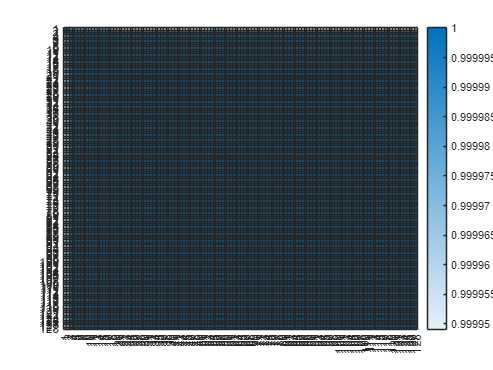

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


% Correlation Matrix Calculation
% Corr_P_L=zeros(Nbus,Nbus);
% for m=1:Nbus
%     for n=1:Nbus
%         S1=0; S2=0; S3=0;
%         for t=1:T
%             S1=S1+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
%             S2=S2+power((P_L_demo(m,t)-P_avg(m,1)),2);
%             S3=S3+power((P_L_demo(n,t)-P_avg(n,1)),2);
%         end
%         Corr_P_L(m,n)=S1/sqrt(S2*S3);
%     end
% end
Corr_V_sim=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S1=0; S2=0; S3=0;
        for t=1:T
            S1=S1+(sorted_sim_voltages(m,t)-V_avg(m,1))*(sorted_sim_voltages(n,t)-V_avg(n,1));
            S2=S2+power((sorted_sim_voltages(m,t)-V_avg(m,1)),2);
            S3=S3+power((sorted_sim_voltages(n,t)-V_avg(n,1)),2);
        end
        Corr_V_sim(m,n)=S1/sqrt(S2*S3);
    end
end
Corr_V_sim;
h=heatmap(Corr_V_sim)

%h.Colormap = flipud(h.Colormap)
% Covariance matrix calculation
% P_L_norm=P_L_demo-P_avg;
% Cov_P_L=cov(P_L_norm)
% Cov_P_L=zeros(Nbus,Nbus);
% for m=1:Nbus
%     for n=1:Nbus
%         S=0;
%         for t=1:T
%             S=S+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
%         end
%         Cov_P_L(m,n)=(1/T)*S;
%     end
% end
% size_cov=size(Cov_P_L);
% heatmap(Cov_P_L)
% Cov_P_L_pu=Cov_P_L/1000;

Cov_V_sim=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S=0;
        for t=1:T
            S=S+(sorted_sim_voltages(m,t)-V_avg(m,1))*(sorted_sim_voltages(n,t)-V_avg(n,1));
        end
        Cov_V_sim(m,n)=(1/T)*S;
    end
end
size_cov=size(Cov_V_sim)

size_cov =    128   128


%heatmap(Cov_V_sim)
% Eigen values (D) and vectors (V) of covariance matrix
[V,D]=eig(Cov_V_sim);
% [V,D]=eig(Corr_P_L);

% Sort eigen vectors
non_sortV=V;
colSums = sum(V);
[sumsorted , sortedIndices] = sort(colSums, 'descend');  % Sort indices in descending order
sortedV = V(:, sortedIndices);  % Rearrange columns based on sorted indices


%%%%%%%%%%%%%%% Online data collection and data recovery %%%%%%%%%%%%%
itrmax=50;
%for itr=1:itrmax
    Ttest=1; % Testing time interval
    L=50; % Total number of data collecting nodes
    
    testpu=data2(:,3); % pu 15-min load at every node
    T1=96;
    % figure
    % t=1:T1;
    % plot(t,testpu(1:T1,1))
    % for n=1:Nbus
    %     for t=1:T1
    %         % S_L_test(n,t)=testpu(t,1)*T_kw(n,1);
    %         S_L_test(n,t)=test(t,1)*sorted_sim_voltages(n,t);
    %     end
    % end
    test_v = xlsread("all_bus_voltages_similar_newest_test.csv")

test_v =        NaN    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000
         0    1.0496    1.0496    1.0396    1.0395    1.0391    1.0389    1.0387    1.0384    1.0324    1.0277    1.0272    1.0271    1.0270    1.0276    1.0209    1.0272    1.0204    1.0201    1.0203    1.0142    1.0138    1.0135    1.0137    1.0132    1.0133    1.0128    1.0129    1.0127    1.0127    1.0128    1.0126    1.0125    1.0125    1.0123    1.0124    1.0205    1.0121    1.0118    1.0115    1.0115    1.0114    1.0109    1.0108    1.0097    1.0093    1.0089    1.0087    1.0086

    S_L_test = test_v(2:end,2:end)'

S_L_test =     1.0496    1.0495    1.0496    1.0496    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0496    1.0496    1.0495    1.0496    1.0496    1.0495    1.0495    1.0495    1.0495    1.0496    1.0496    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0496    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0495    1.0496    1.0495
    1.0496    1.0495    1.0496    1.0496    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0496    1.0496    1.0495    1.0496    1.0496    1.0495    1.0495    1.0495    1.0495    1.0496    1.0496    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0495    1.0496    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0495    1.0495    1.0495    1.0496    1.0495    1.04

    % figure
    % plot(S_L_test(:,1))
    
    
    % UL=sortedV(:,1:L);
    UL=sortedV(:,1); % only one principal component
    S_L=ones(Nbus,1);
    %S_L = V_avg;
    %S_L = V_avg % Original power at collected nodes
    % n_L=(randperm(Nbus, L))'; % Index of selected node 
    
    % Identify nodes having loads
    k=1;
    for n=1:Nbus
        if T_kw(n,1)~=0
            n_load(k,1)=n;
            k=k+1;
        end
    end
    
    i_L=(randperm(length(n_load), L))' % Index of selected item from n_load

i_L =      2
    32
    74
    85
     3
    16
    69
    42
    17
    59


    
    % Selected Node and their actual measurement
    n_L=zeros(L,1);
    for l=1:L
        n_L(l,1)=n_load(i_L(l,1),1);
    end
    n_L

n_L =      4
    52
   110
   125
     6
    26
   103
    66
    30
    90




    for l=1:L
        S_L(n_L(l,1),1,1)=S_L_test(n_L(l,1),1); %-V_avg(n_L(l,1),1);
        
    end
    S_L = S_L - V_avg;
    testpu(Ttest,1)

ans = 0.9729

    % Recovered data
    S_L_rec=V_avg+UL*UL'*S_L;

    % Integrated normalized absolute error (INAE)
    S_test_tot=zeros(1,T1);
    for t=1:T1
        for n=1:Nbus
            S_test_tot(1,t)=S_test_tot(1,t)+S_L_test(n,t);
        end
    end


    S_rec_tot=0;
    for n=1:Nbus
        S_rec_tot=S_rec_tot+abs(S_L_test(n,Ttest)-S_L_rec(n,1));
    end
    INAE=S_rec_tot/S_test_tot(1,Ttest)

INAE = 3.5802e-04


    %Error(itr,1)=INAE*100;
 %end


figure
T=1:Nbus;
p=plot(T,[S_L_test(:,Ttest),S_L_rec(:,1)])

p =   2×1 Line array:

  Line
  Line


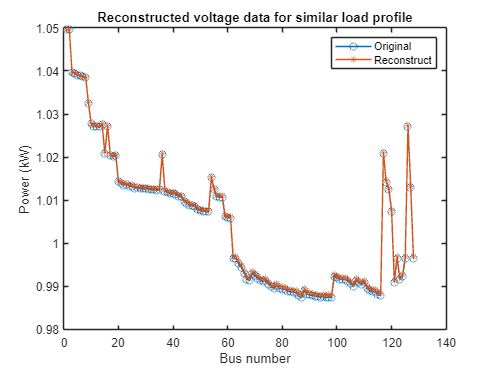

legend(["Original" "Reconstruct"])
p(1).Marker = 'o';
p(2).Marker = '*';
title('Reconstructed voltage data for similar load profile')
ylabel('Power (kW)')
xlabel('Bus number')


% 
% 
% 
% 